**Question 1**

Remember to assign your answers to the pre-existing variables, and do not change their names. You may create other variables if you wish, but the auto-grader will not see them.

% YOUR CODE BELOW
h1 = [0,0,0,0,0,0,1,0,0,0,0]; %REPLACE WITH YOUR ANSWER

h2 = [0,0,0,0,0.5,0,0,0,1,0,0]; %REPLACE WITH YOUR ANSWER

h3 = zeros(11, 1);
for m = -5:5
    y = m * (-1)^m;
    h3(m+6) = y; 
    %REPLACE WITH YOUR ANSWER
end

% PLOTTING - NO NEED TO EDIT
disp('Question 1 Figures')

Question 1 Figures


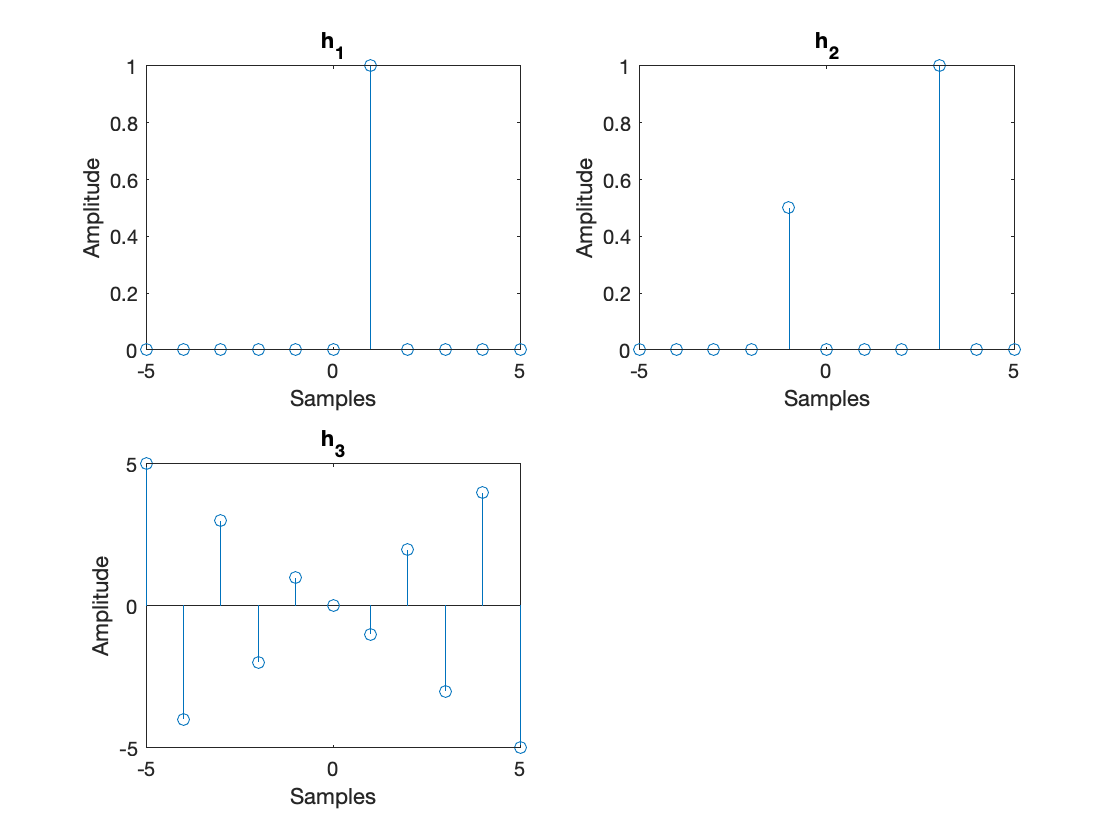

figure; 
subplot(2,2,1); stem(-5:5, h1); title('h_1');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,2); stem(-5:5, h2); title('h_2');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,3); stem(-5:5, h3); title('h_3');
xlabel('Samples'); ylabel('Amplitude');

**Question 2**

x = [0,0,0,0,0,1,1,1,1,0,0]; %REPLACE WITH YOUR INPUT SIGNAL

n = -10:10; %REPLACE WITH YOUR ANSWER

h4 = [0,0,0,0,0,1,0,0,0,0,0]; %REPLACE WITH IMPULSE RESPONSE OF SYSTEM
y4 = conv(x,h4); %REPLACE WITH OUTPUT OF SYSTEM

h5 = [-2,0,0,0,0,0,0,1,0,0,0]; %REPLACE WITH IMPULSE RESPONSE OF SYSTEM
y5 = conv(x,h5); %REPLACE WITH OUTPUT OF SYSTEM

h6 = [0,0,0,0,1,0,1,0,0,0,0]; %REPLACE WITH IMPULSE RESPONSE OF SYSTEM
y6 = conv(x,h6); %REPLACE WITH OUTPUT OF SYSTEM

h7 = [0,1,0,-1,0,1,0,-1,0,1,0]; %REPLACE WITH IMPULSE RESPONSE OF SYSTEM
y7 = conv(x,h7); %REPLACE WITH OUTPUT OF SYSTEM

% PLOTTING - NO NEED TO EDIT
disp('Question 2 Figures')

Question 2 Figures


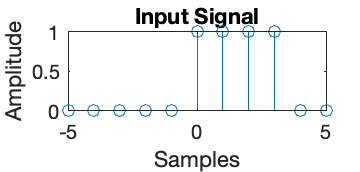

figure; 
set(gcf, 'Units', 'Inches', 'Position',[0 0 2.5 1.2])
stem(-5:5, x); title('Input Signal')
xlabel('Samples'); ylabel('Amplitude');

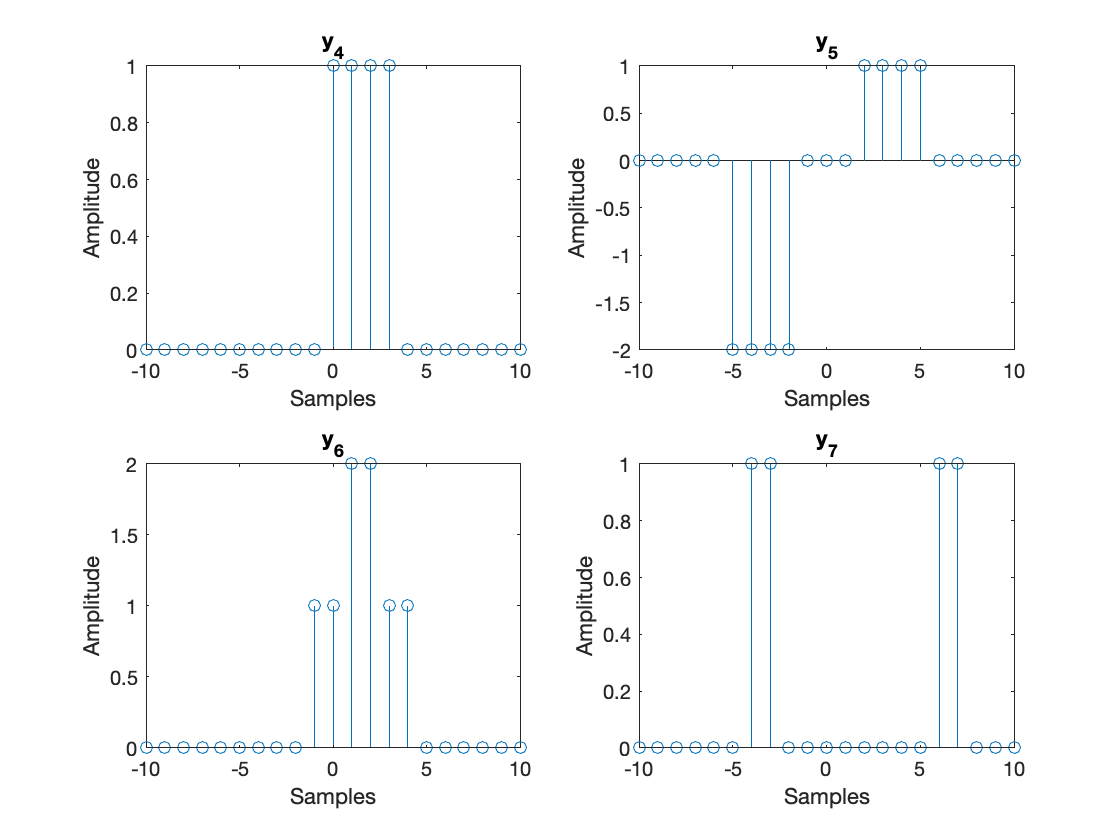


figure; 
subplot(2,2,1); stem(n, y4); title('y_4');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,2); stem(n, y5); title('y_5');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,3); stem(n, y6); title('y_6');
xlabel('Samples'); ylabel('Amplitude');
subplot(2,2,4); stem(n, y7); title('y_7');
xlabel('Samples'); ylabel('Amplitude');

**Question 3**

%LOAD THE PROVIDED MAT FILE (PLEASE DON'T REMOVE)
load('code2_fall21.mat')

%YOUR CODE HERE

[a,b] = methods(code,noisy_message);
%Feel free to experiment!
%You can create your own plots and zoom in to check your answer.
% Plotting
c = noisy_message(a+1:a+length(code));
disp('check the answer')

check the answer


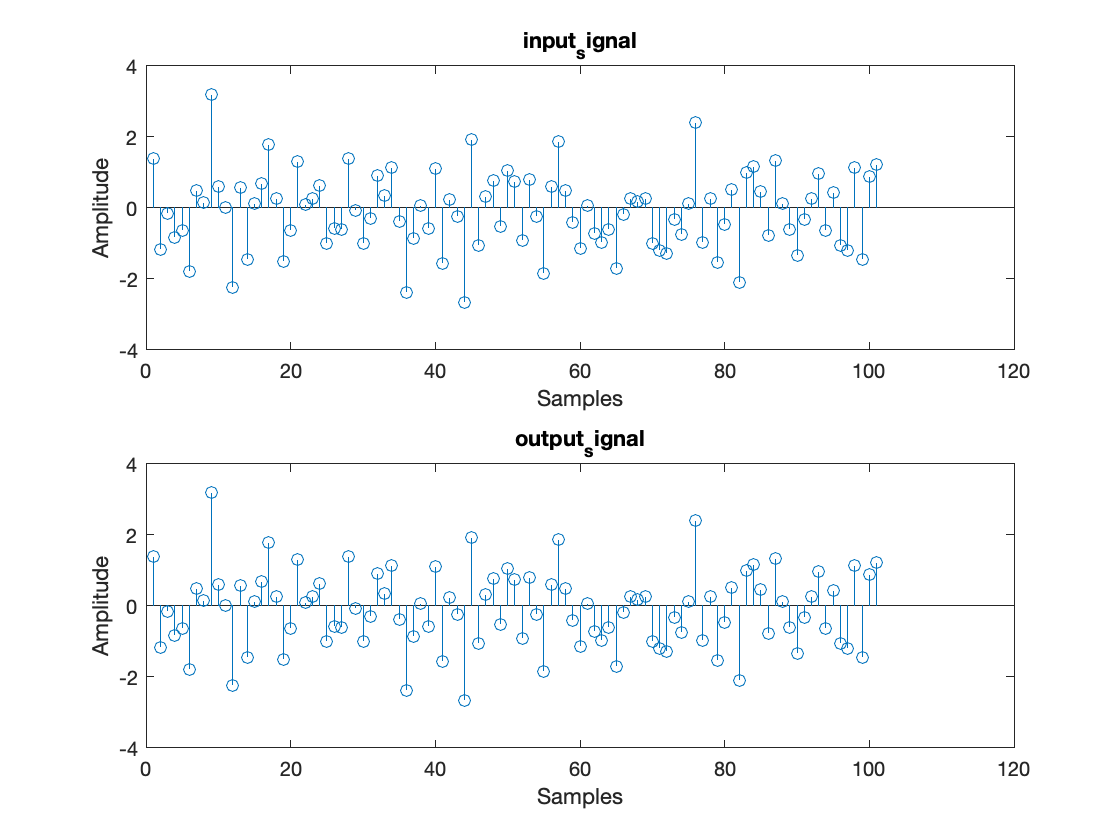

figure;
subplot(2,1,1);stem(code);title('input_signal');
xlabel('Samples');ylabel('Amplitude');
subplot(2,1,2);stem(c);title('output_signal');
xlabel('Samples');ylabel('Amplitude');



%ANSWER
location = a; %REPLACE WITH YOUR ANSWER


**Functions**

Here's some space for function definitions, if you choose to make any.

function [y,z] = methods(u,v)
% this function is used for finding a small segment of code's location hidden in a
% larger signal, based on Cauchy-Schwarz Inequality.
% constrct a special convolution on target code, 
% it must have a point m = M to make this convolution maximal
% M is the target code location in a larger signal

    % inital variables 
    v_seg = v(1:length(u));
    u_re = fliplr(u);
    
    % first, figure out the maximum of convolution
    conv1 = conv(u_re,u);
    
    % second, constrct a special convolution on target code, let this
    % convolution value equal to the maximum of convolution squares, find M. 
    for m = 0:(length(v)-length(u))
        
        % roll to create new segment of code          
        for j = 1:length(u)
            v_seg(j) = v(m + j);
        end
        
        % solution 1
        v_seg_new = fliplr(v_seg) ;
        conv2 = conv(v_seg_new,v_seg);
        conv3 = max(conv1 .* conv2);
        if conv3 == max(conv1)^2
            y = m;
            z = conv1;
            break;
        end
        
        % solution 2        
%         if max(conv(fliplr(v_seg),v_seg)) == max(conv1)
%             y = m;
%             z = conv1;
%             break;
%         end
    end
    
end
